# 1. Étude du modèle linéaire, continu et invariant dans le temps.

clc;clear;
K_m =0.5;
K_r=0.4;
tau_r=0.1;
tau_m=0.5;
tau_c=0.05;
usat=5;
H=1;
C=10;

% 1. Get the actual location of this Live Script
currentFile = matlab.desktop.editor.getActiveFilename;
currentFileFolder = fileparts(currentFile);

% 2. Build the path and resolve the '..' immediately 
rawPath = fullfile(currentFileFolder, '..', 'Devoir_01_Latex', 'src', 'figs');
jFile = java.io.File(rawPath);
outDir = char(jFile.getCanonicalPath()); % This removes the '..' and gives a clean string

if ~exist(outDir,'dir')
    mkdir(outDir);
end

## a)


s = tf('s');

e_to_x = (C) * (K_m/(tau_m*s+1))* (K_r/(s*(tau_r*s+1))); 

F= e_to_x/(1+e_to_x);

syms s;

[num, den] = tfdata(F, 'v');

k = den(1);          % leading denominator coefficient

num_n = num / k;
den_n = den / k;

F_sym = poly2sym(num_n, s) / poly2sym(den_n, s);

F_sym_simplified = simplify(F_sym)

$$F\_sym\_simplified = \frac{40}{s^{3}+12\,s^{2}+20\,s+40}$$


latex(F_sym_simplified)

ans = '\frac{40}{s^3+12\,s^2+20\,s+40}'


% split into numerator/denominator
[numS, denS] = numden(F_sym_simplified);

% convert to coefficient vectors (descending powers of s)
num = sym2poly(numS);
den = sym2poly(denS);

% (optional) normalize so den(1)=1
num = num/den(1)

num = 40

den = den/den(1)

den =      1    12    20    40


## c)

%from Controllable Canonical Form n=3, m=0


A= [[0 1 0];
    [0 0 1];
    [-den(1,4) -den(1,3) -den(1,2)]]

A =      0     1     0
     0     0     1
   -40   -20   -12


B = transpose([ 0 0 1])

B =      0
     0
     1


C_mat = [num(1,1) 0 0]

C_mat =     40     0     0


D = 0

D = 0

## d)

% --- (c) Analytical time responses ---

syms s t;

F= F_sym_simplified;
R= [2 2/s 2/s/s]

$$R = \left(\begin{array}{ccc} 2 & \frac{2}{s} & \frac{2}{s^{2}} \end{array}\right)$$

Y = sym(zeros(1, numel(R)));
y = sym(zeros(1, numel(R)));

for i= 1:numel(R)
    Y(i) = F* R(i);

    [num_Y_i, den_Y_i] = numden(Y(i));
    num_vec = sym2poly(expand(num_Y_i));
    den_vec = sym2poly(expand(den_Y_i));
    [Res,P,~] = residue(num_vec, den_vec);
    
    y(i) = sum(Res .* exp(P*t));
    simplify(y);
    fprintf("y(%d)=",i);
    disp(vpa(y(i),4));
    latex(vpa(y(i),4));
end

y(1)=

$$0.8255\,{\mathrm{e}}^{-10.45\,t}+{\mathrm{e}}^{t\,\left(-0.7736-1.797\,\mathrm{i}\right)}\,\left(-0.4127+2.223\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(-0.7736+1.797\,\mathrm{i}\right)}\,\left(-0.4127-2.223\,\mathrm{i}\right)$$

y(2)=

$$2.0-0.07897\,{\mathrm{e}}^{-10.45\,t}+{\mathrm{e}}^{t\,\left(-0.7736-1.797\,\mathrm{i}\right)}\,\left(-0.9605-0.6433\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(-0.7736+1.797\,\mathrm{i}\right)}\,\left(-0.9605+0.6433\,\mathrm{i}\right)$$

y(3)=

$$0.007555\,{\mathrm{e}}^{-10.45\,t}+1.0+{\mathrm{e}}^{t\,\left(-0.7736-1.797\,\mathrm{i}\right)}\,\left(0.4962-0.3209\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(-0.7736+1.797\,\mathrm{i}\right)}\,\left(0.4962+0.3209\,\mathrm{i}\right)$$

## e)

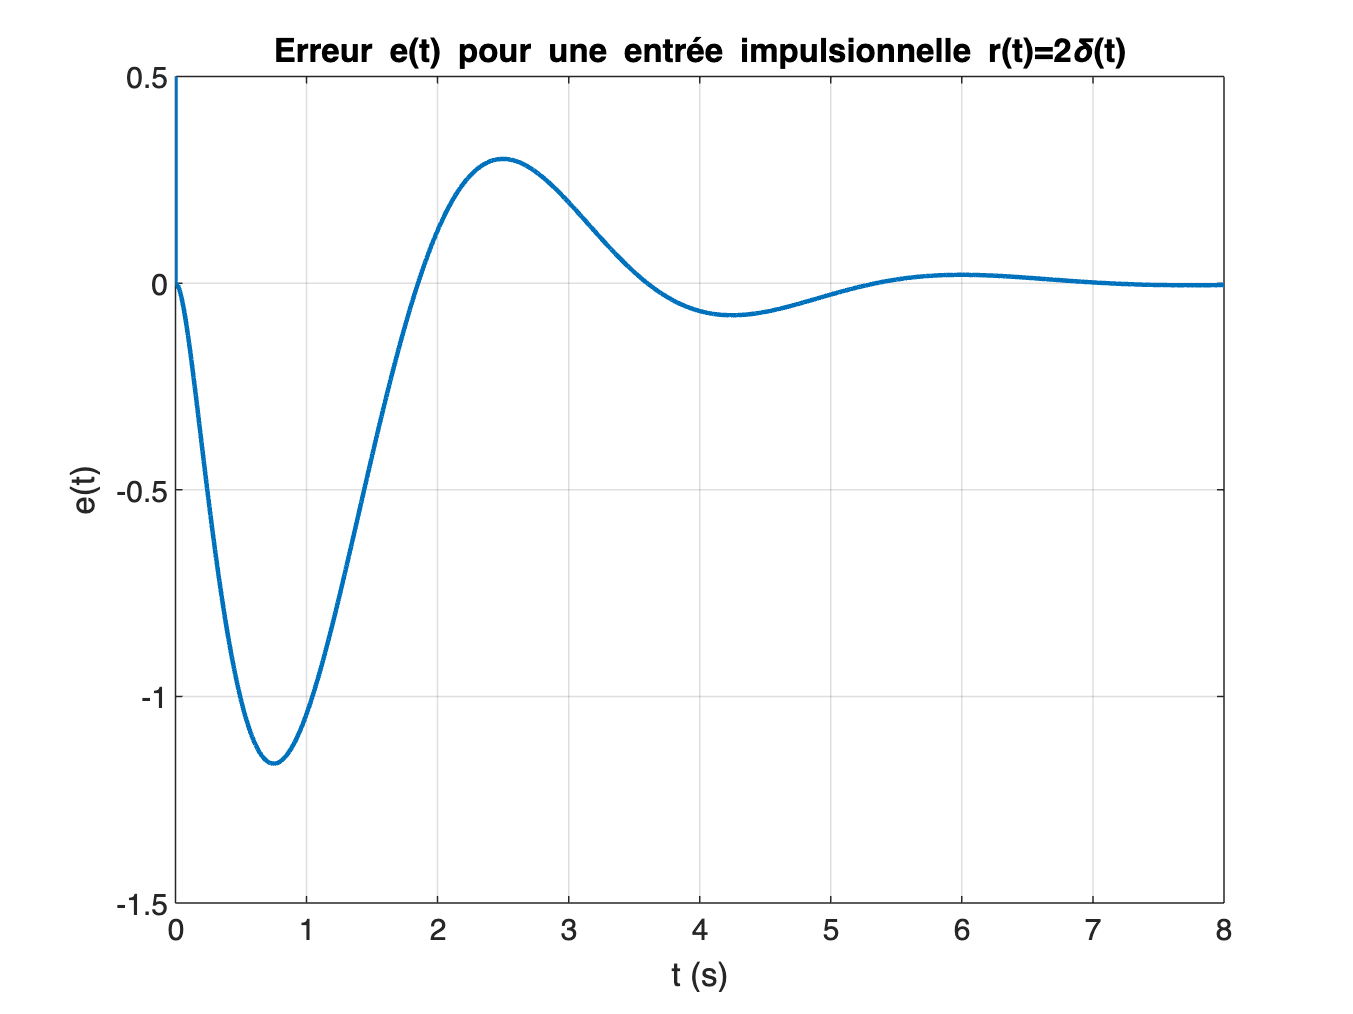

t_2s =7.976200e+00 pour err(end) =-4.633321e-03

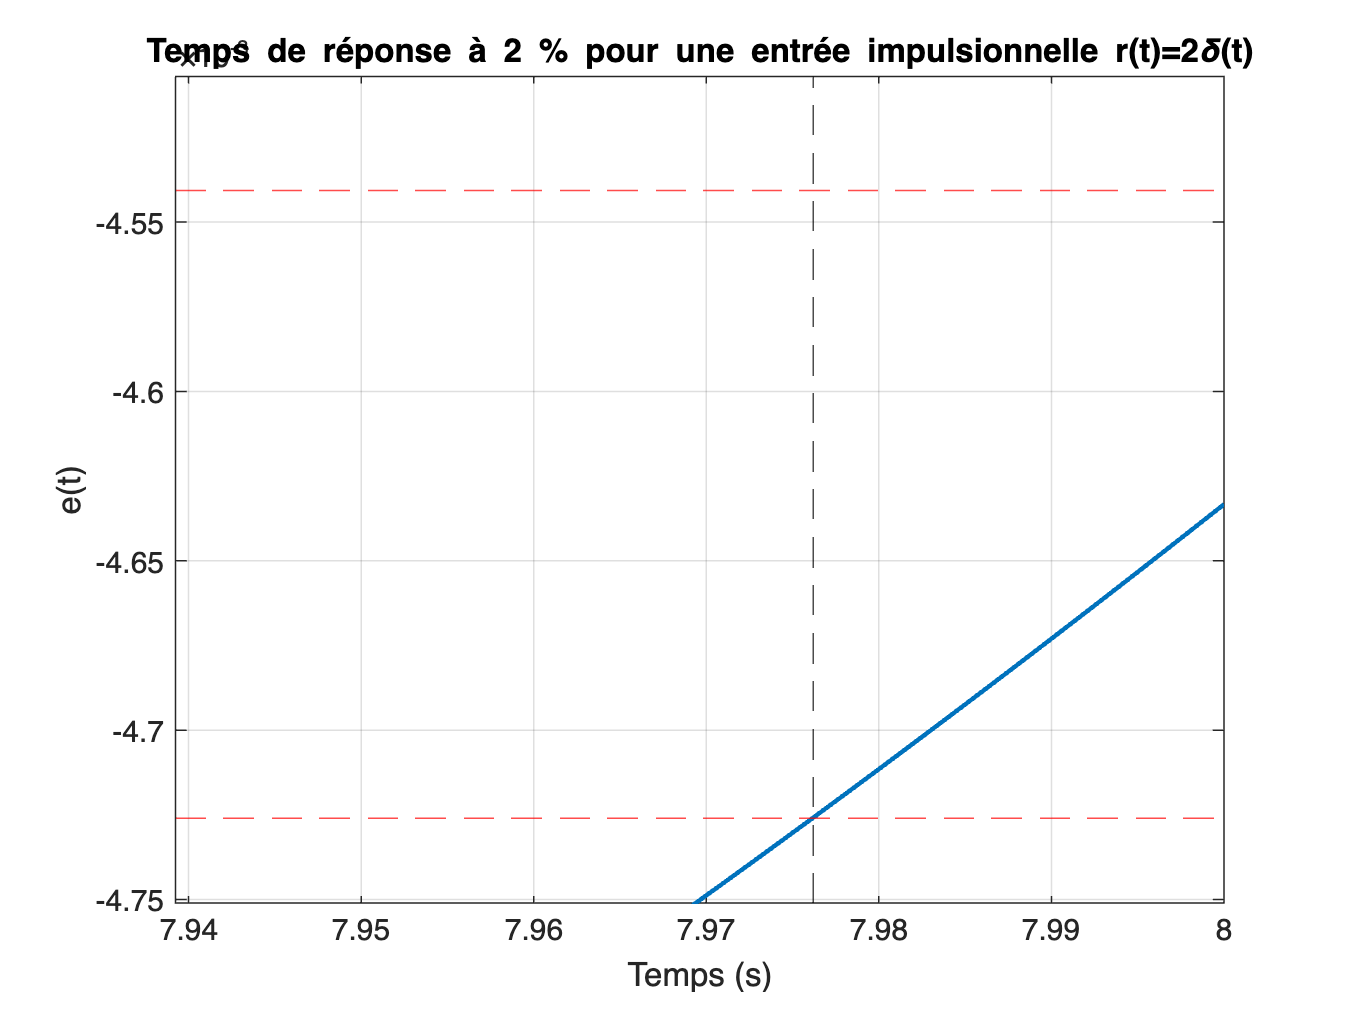

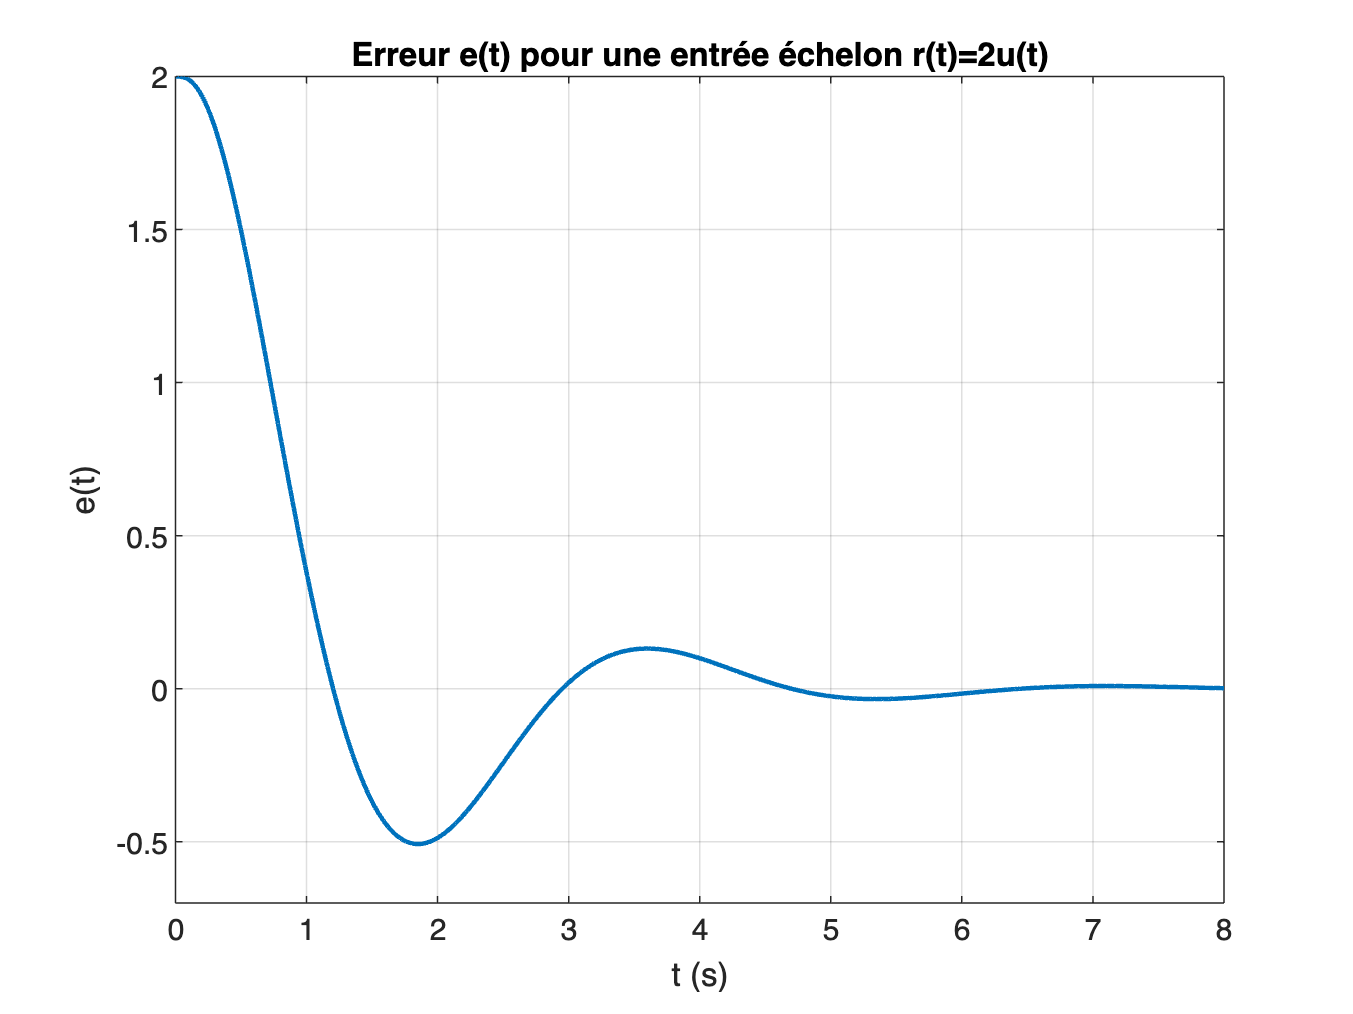

t_2s =7.996500e+00 pour err(end) =1.641967e-03

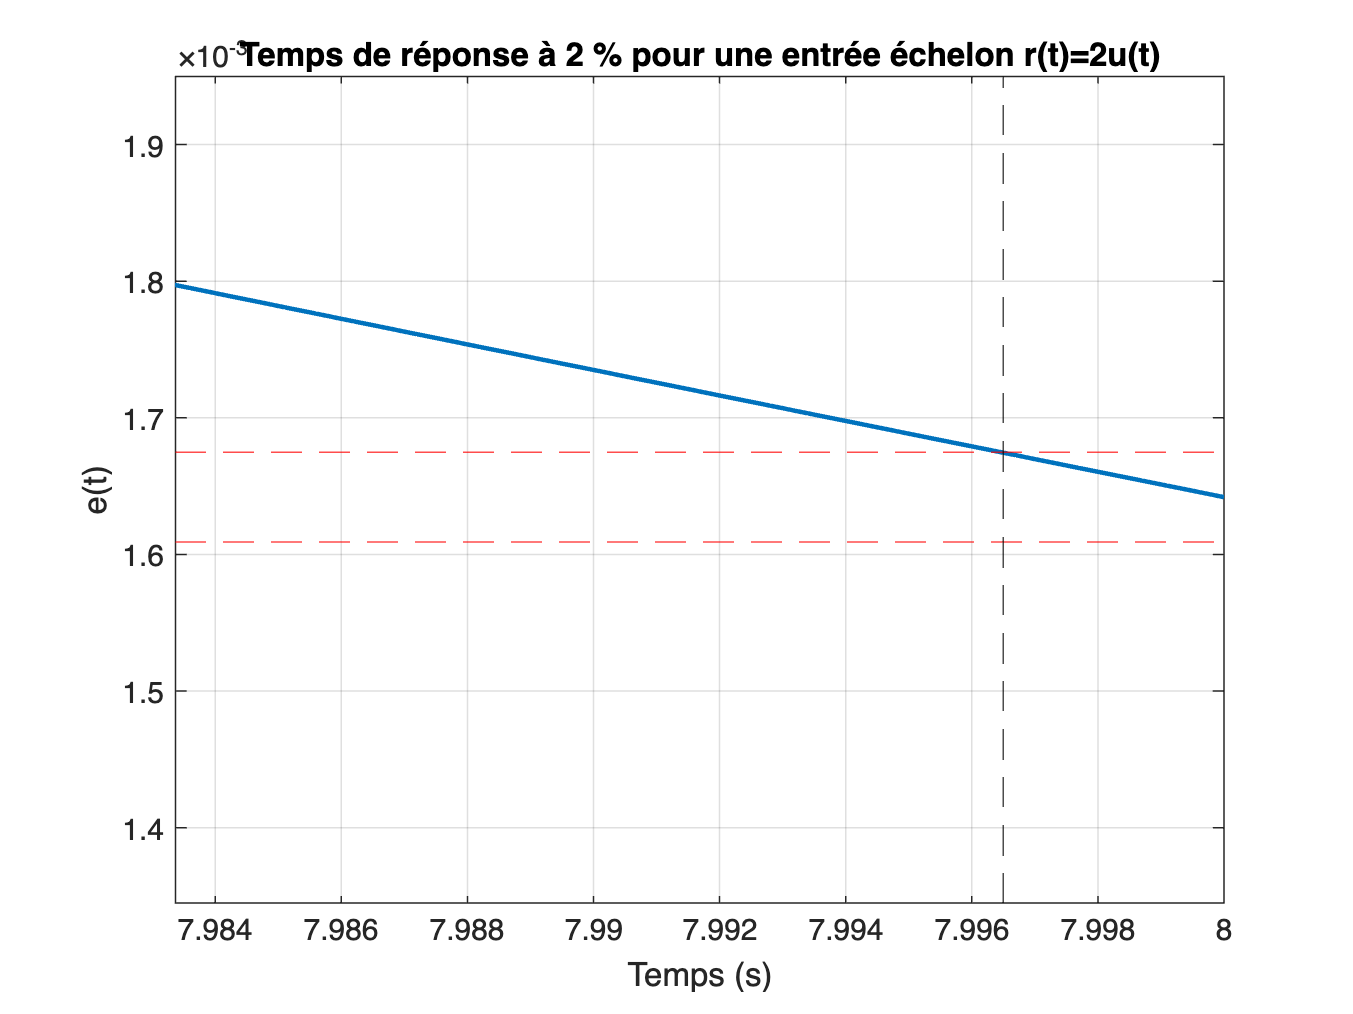

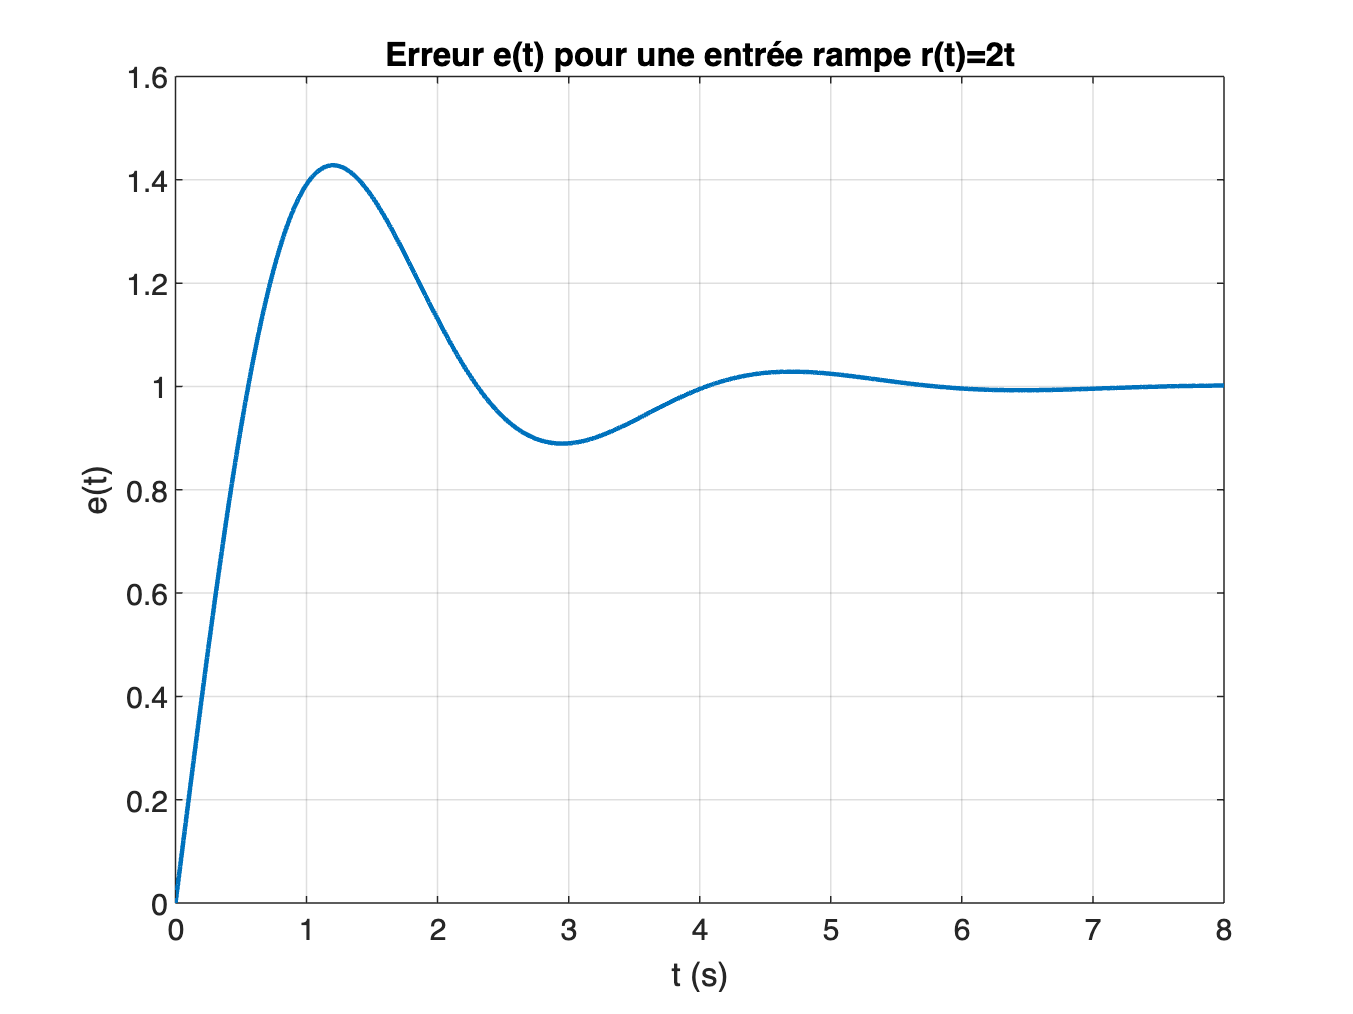

t_2s =5.098600e+00 pour err(end) =1.001758e+00

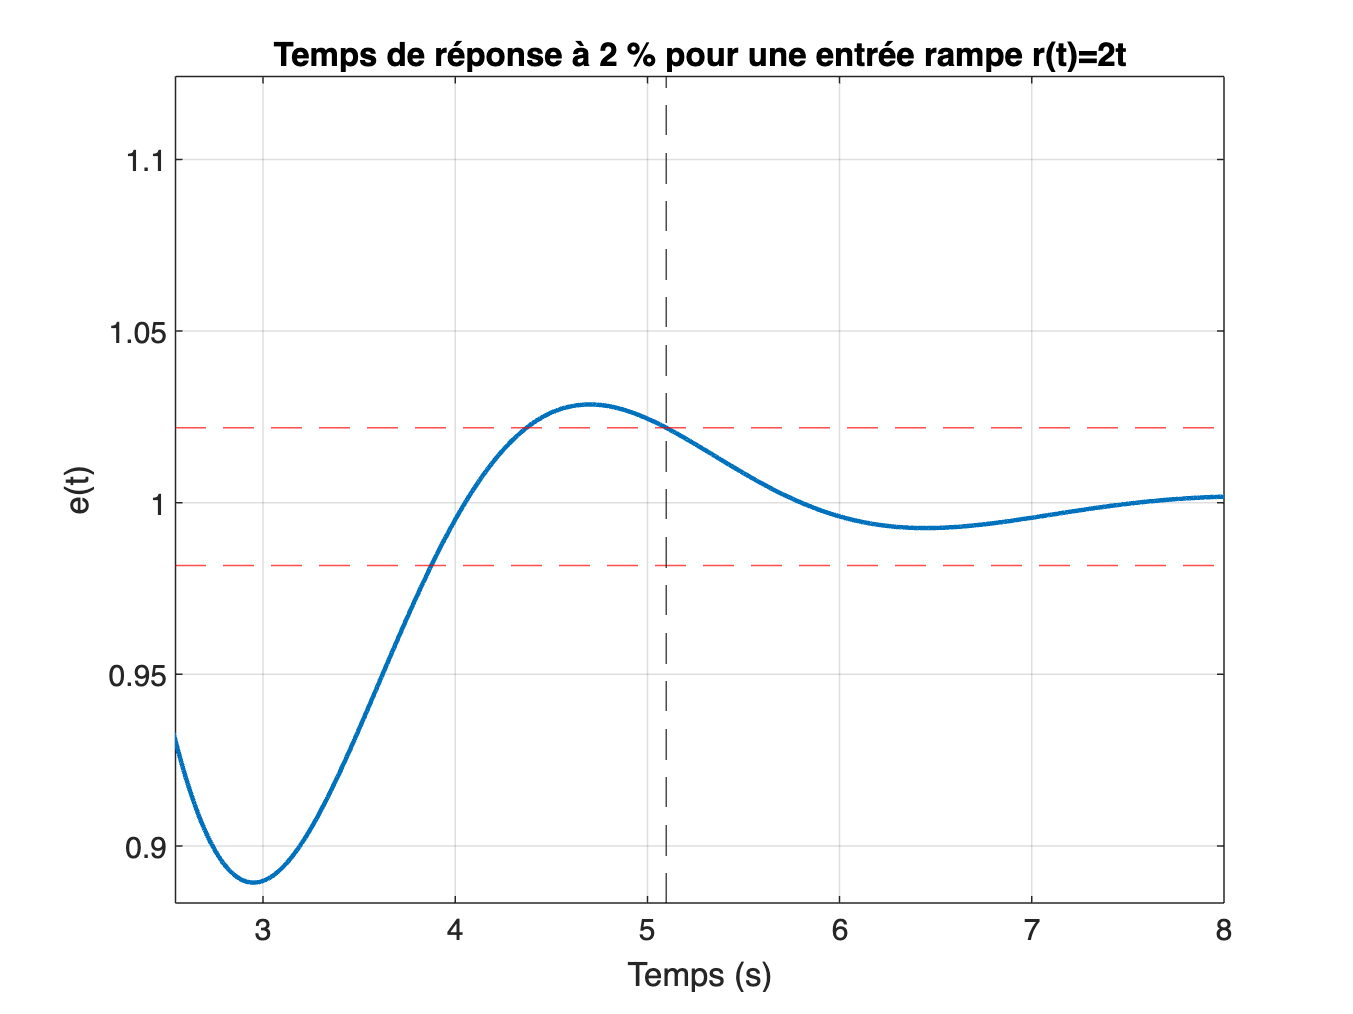

timeOfSimulation= 8;
dt = 0.0001;
t = (0:dt:timeOfSimulation);

titrePlotErreur = {
    'Erreur e(t) pour une entrée impulsionnelle r(t)=2\delta(t)';
    'Erreur e(t) pour une entrée échelon r(t)=2u(t)';
    'Erreur e(t) pour une entrée rampe r(t)=2t'};
nomFichierExportErreur = {
    'erreur_impulsion.png';
    'erreur_echelon.png';
    'erreur_rampe.png'};
titrePlotTempsRep = {
    'Temps de réponse à 2 % pour une entrée impulsionnelle r(t)=2\delta(t)';
    'Temps de réponse à 2 % pour une entrée échelon r(t)=2u(t)';
    'Temps de réponse à 2 % pour une entrée rampe r(t)=2t'};
nomFichierExportTempsRep = {
    'TempsRep_impulsion.png';
    'TempsRep_echelon.png';
    'TempsRep_rampe.png'};
scalingFactors = [ 
    [1 10];
    [1 100];
    [0.5 0.1]];
errorYLims = [ 
    [-1.5 0.5];
    [-0.7 2];
    [0 1.6]];

% pour impulsion

u_imp = zeros(size(t));

u_imp(1) = 2/dt;        

% pour échelon
   
u_ech = 2*ones(size(t));    

% pour rampe

u_ram = 2*t;    

simin_list =[
    timeseries(u_imp,t);
    timeseries(u_ech,t);
    timeseries(u_ram,t)];

for i = 1:numel(simin_list)

    simin= simin_list(i);

    data = sim('Sim_01.slx', ...
        'Solver','ode4', ...
        'FixedStep',num2str(dt), ...
        'StopTime', num2str(timeOfSimulation));
    
    t   = data.e.Time;
    err = data.e.Data;
    
    figure
    plot(t,err,'LineWidth',1.5), grid on
    title(titrePlotErreur(i))
    ylim([errorYLims(i,1),errorYLims(i,2)]); 
    xlabel('t (s)')
    ylabel('e(t)')
    print(gcf, fullfile(outDir,nomFichierExportErreur{i}), '-dpng', '-r300');
    hold off
    
    err_final = err(end);
    borne_sup = max([0.98*err_final 1.02*err_final]);
    borne_inf = min([0.98*err_final 1.02*err_final]);
    
    t_2s = 0;
    for j=1:numel(err)
        if (err(j)>borne_sup || err(j)<borne_inf)
            if(j==numel(err))
                t_2s = t(j);
            else
                t_2s = t(j+1);
            end
        end
    end
    fprintf('t_2s =%d pour err(end) =%d',t_2s,err(end));
    dispHorFactor= scalingFactors(i,1)*err(end);
    dispVertFactor= scalingFactors(i,2)*err(end);
    figure
    plot(t,err,'LineWidth',1.5); 
    grid on;
    hold on;
    title(titrePlotTempsRep{i})
    yline(borne_sup,'r--')
    yline(borne_inf,'r--')
    xline(t_2s,'k--');
    xlabel('Temps (s)')
    ylabel('e(t)')
    xmin = max([min([t_2s*(1-dispHorFactor) t_2s*(1+dispHorFactor) t(end)]) t(1)]);
    xmax = min([max([t_2s*(1-dispHorFactor) t_2s*(1+dispHorFactor) t(end)]) t(end)]);
    xlim([xmin xmax]);
    ymin = min([borne_inf-abs(borne_inf)*dispVertFactor borne_sup+abs(borne_sup)*dispVertFactor]);
    ymax = max([borne_inf-abs(borne_inf)*dispVertFactor borne_sup+abs(borne_sup)*dispVertFactor]);
    ylim([ymin, ymax]);
    print(gcf, fullfile(outDir,nomFichierExportTempsRep{i}), '-dpng', '-r300')
    hold off
end

## 2.a)


timeOfSimulation= 8;
dt = 0.0001;
t = (0:dt:timeOfSimulation);
errorYLims = [-1 2];

tau_c_step=0.05;
tau_c_min = 0;
tau_c_max = 0.05;

tau_c_list = (tau_c_min:tau_c_step:tau_c_max);

titrePlotErreur = {
    'Erreur e(t) pour une entrée échelon r(t)=2t avec délai'};
nomFichierExportErreur = {
    'erreur_echelon_delai.png'};


% pour échelon
   
u_ech = 2*ones(size(t));    
 

simin_list =[
    timeseries(u_ech,t);];

for i = 1:numel(simin_list)

    simin= simin_list(i);

    f = figure('Visible','on');  % figure classique (pas uifigure)
    ax = axes('Parent',f); hold(ax,'on');
    legendText = cell(1, numel(tau_c_list));
    for j= 1:numel(tau_c_list)
        tau_c=tau_c_list(j);

        data = sim('Sim_02.slx', ...
            'Solver','ode4', ...
            'FixedStep',num2str(dt), ...
            'StopTime', num2str(timeOfSimulation));
        
        t   = data.e.Time;
        err = data.e.Data;
     
    plot(ax, t, err, 'LineWidth', 1.5);
        grid(ax,'on');
        legendText{j} = sprintf('$\\tau_c = %.2f$', tau_c);

    end
    title(titrePlotErreur(i))
    ylim([errorYLims(i,1),errorYLims(i,2)]); 
    xlabel('t (s)');
    ylabel('e(t)');
    legend(legendText, ...
       'Interpreter','latex', ...
       'Location','best');
    % print(gcf, nomFicherExportErreur{i}, '-dpng', '-r300');
                      
    exportgraphics(f, fullfile(outDir,nomFichierExportErreur{i}), 'Resolution', 300);
    close(f);
    hold off
end

## 2.b)


timeOfSimulation= 50;
dt = 0.0001;
t = (0:dt:timeOfSimulation);
errorYLims = [-2.2 2.2];
tau_c_step=0.05;
tau_c_min = 0;
tau_c_max = 0.5;

tau_c_list = (tau_c_min:tau_c_step:tau_c_max);

titrePlotErreur = {
    'Erreur e(t) pour une entrée échelon r(t)=2t avec délai multiple'};
nomFichierExportErreur = {
    'erreur_echelon_delai_multiples.png'};


% pour échelon
   
u_ech = 2*ones(size(t));    
 

simin_list =[
    timeseries(u_ech,t);];

for i = 1:numel(simin_list)

    simin= simin_list(i);

    % figure; hold on;
    f = figure('Visible','on');  % figure classique (pas uifigure)
    ax = axes('Parent',f); hold(ax,'on');
    legendText = cell(1, numel(tau_c_list));
    for j= 1:numel(tau_c_list)
        tau_c=tau_c_list(j);

        data = sim('Sim_02.slx', ...
            'Solver','ode4', ...
            'FixedStep',num2str(dt), ...
            'StopTime', num2str(timeOfSimulation));
        
        t   = data.e.Time;
        err = data.e.Data;
     
        plot(ax, t, err, 'LineWidth', 1.5);
        grid(ax,'on');
        legendText{j} = sprintf('$\\tau_c = %.2f$', tau_c);

    end
    title(titrePlotErreur(i))
    ylim([errorYLims(i,1),errorYLims(i,2)]); 
    xlabel('t (s)');
    ylabel('e(t)');
    legend(legendText, ...
       'Interpreter','latex', ...
       'Location','southeast');
    % print(gcf, nomFicherExportErreur{i}, '-dpng', '-r300');
                      
    exportgraphics(f, fullfile(outDir,nomFichierExportErreur{i}), 'Resolution', 300);
    close(f);
    hold off
end

## 3

timeOfSimulation= 10;
dt = 0.0001;
t = (0:dt:timeOfSimulation);
errorYLims = [-5 40];

titrePlotErreur = {
    'Erreur e(t)pour une entrée échelon r(t)=10 avec Saturation';
    'Position x(t), \omega et \omega_{sat}'};
nomFichierExportErreur = {
    'position_echelon_saturation.png';};


% pour échelon
   
u_ech = 10*ones(size(t));    
 
simin_list =[
    timeseries(u_ech,t);];

for i = 1:numel(simin_list)

    simin= simin_list(i);

    % figure; hold on;
    f = figure('Visible','on');  % figure classique (pas uifigure)
    ax = axes('Parent',f); hold(ax,'on');

    data = sim('Sim_03.slx', ...
        'Solver','ode4', ...
        'FixedStep',num2str(dt), ...
        'StopTime', num2str(timeOfSimulation));
    
    t   = data.x.Time;
    x = data.x.Data;
    omega = data.omega.Data;
    omega_sat = data.omega_sat.Data;
 
    plot(ax, t, x, 'LineWidth', 1.5);
    grid(ax,'on');

    title(titrePlotErreur(i))
    ylim([errorYLims(i,1),errorYLims(i,2)]); 
    xlabel('t (s)');

    % print(gcf, nomFicherExportErreur{i}, '-dpng', '-r300');
                      
    % exportgraphics(f, nomFichierExportErreur{i}, 'Resolution', 300);
    % close(f);
    % hold off
    % 
    % f = figure('Visible','on');  % figure classique (pas uifigure)
    % ax = axes('Parent',f); hold(ax,'on');
    plot(ax, t, omega, 'LineWidth', 1.5);
    plot(ax, t, omega_sat, 'LineWidth', 1.5);
    grid(ax,'on');

    title(titrePlotErreur(2))
    xlabel('t (s)');
    ylabel('');
    legendText = {
            sprintf('x(t)');
            sprintf('$\\omega$');
        sprintf('$\\omega_{sat}$')};
    legend(legendText, ...
       'Interpreter','latex', ...
       'Location','best');
    % print(gcf, nomFicherExportErreur{i}, '-dpng', '-r300');
                      
    exportgraphics(f, fullfile(outDir,nomFichierExportErreur{i}), 'Resolution', 300);
    close(f);
    hold off
end